# Morphological filtering

1. Load ảnh

I = imread('niga1.png');
if size(I, 3) == 3
    I_gray = rgb2gray(I);
else
    I_gray = I;
end

I = im2uint8(I);

2. Binarization

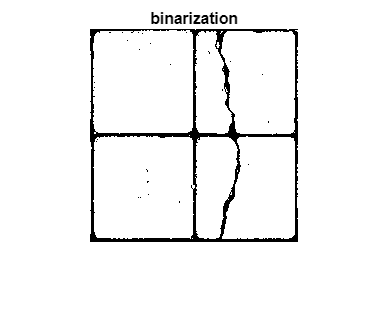

level = graythresh(I_gray);
J2 = imbinarize(I_gray, level);

figure; imshow(J2); title("binarization")

3.  Dùng dilation and erosion áp dụng cho ảnh J2 với kích thước cửa sổ neighborhood là 5x5

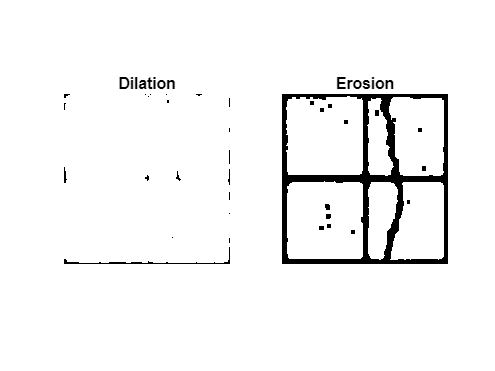

% Tạo cửa sổ neighborhood 5x5
se = strel('square', 5);

% Thực hiện Dilation (Nở) và Erosion (Co)
J_dilate = imdilate(J2, se);
J_erode = imerode(J2, se);

figure;
subplot(1,2,1); imshow(J_dilate); title('Dilation');
subplot(1,2,2); imshow(J_erode); title('Erosion');

4. Sử dụng các bộ lọc dựa trên kết hợp dilation và erosion (slide) để điều chỉnh sao cho thấy rõ vết nứt/vỡ nhất

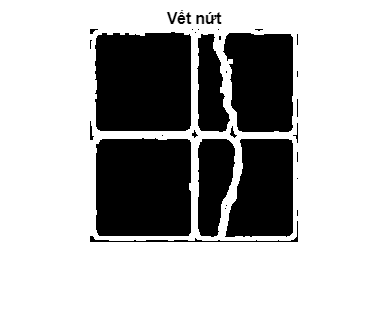

% Tách vết nứt rõ nhất = Morphological Gradient
se = strel('disk', 3);

J_dilate = imdilate(J2, se);
J_erode  = imerode(J2, se);

% Gradient hình thái = Dilation - Erosion
J_cracks = imsubtract(J_dilate, J_erode);

% Loại bỏ các vùng trắng nhỏ hơn ngưỡng
J_cracks = bwareaopen(J_cracks, 5000);

figure;
imshow(J_cracks); title('Vết nứt');

5. Sử dụng các bộ lọc kết hợp dilation và erosion để điều chỉnh sao cho không còn thấy vết nứt/vỡ (Ảnh J5)

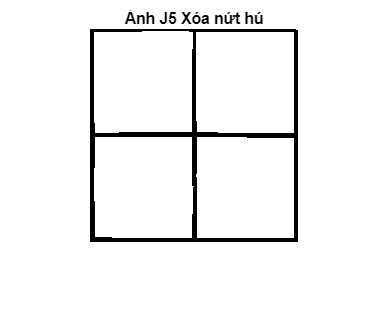

% Giữ lại đường kẻ dọc
se_v = strel('line', 40, 90); 
vertical_lines = imerode(imdilate(J2, se_v), se_v);

% Giữ lại đường kẻ ngang
se_h = strel('line', 40, 0); 
horizontal_lines = imerode(imdilate(J2, se_h), se_h);

J5 = vertical_lines & horizontal_lines;

se = strel('square', 3); 
J5_erosion = imerode(J5, se);
%J_dilate = imdilate(J5, se)

J5 = bwareaopen(J5, 100);

figure;
imshow(J5_erosion); title('Ảnh J5 Xóa nứt hú');

j5 = J5_erosion;

6. Đếm số viên gạch

[L, num_raw] = bwlabel(J5);

% Tính diện tích + hình dạng
stats = regionprops(L, 'Area', 'Extent', 'Solidity');
areas = [stats.Area];
extents = [stats.Extent];
solidities = [stats.Solidity];

% Lọc theo diện tích + hình dạng
threshold_area = 1500;
threshold_extent = 0.5; % diện tích vùng/bounding box
threshold_solidity = 0.5; % Diện tích vùng/Diện tích convex hull

valid_labels = find( ...
    areas > threshold_area & ...
    extents > threshold_extent & ...
    solidities > threshold_solidity ...
);
num = length(valid_labels);
fprintf('Số lượng ô gạch đếm được là: %d\n', num);

Số lượng ô gạch đếm được là: 4


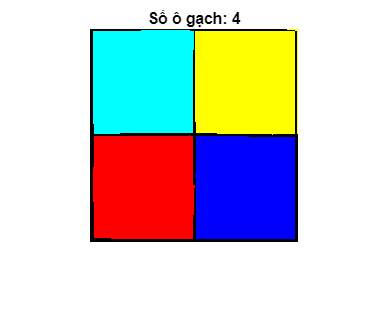


L_filtered = ismember(L, valid_labels);
[L2, ~] = bwlabel(L_filtered);
RGB_label = label2rgb(L2, @jet, 'k', 'shuffle');

figure;
imshow(RGB_label); title(['Số ô gạch: ', num2str(num)]);

7. 

Quay lại ảnh gốc ban đầu. 

Chuyển về dạng ảnh xám grayscale. Thêm 10% nhiễu salt and pepper. 

Hãy lọc nhiễu bằng bộ lọc median (Cài đặt thủ công, không dùng bộ lọc có sẵn).

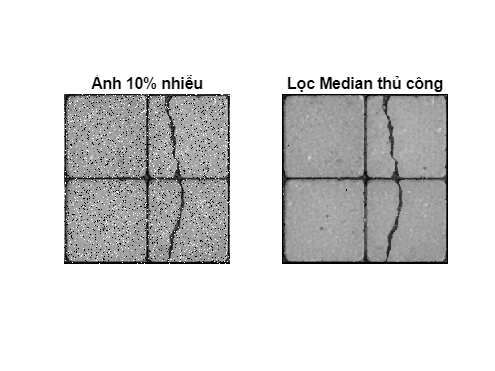

% Quay lại ảnh xám gốc
I_noise = imnoise(I_gray, 'salt & pepper', 0.10);

[rows, cols] = size(I_noise);
J_median = zeros(rows, cols, 'uint8');

% Cài đặt bộ lọc Median thủ công (cửa sổ 3x3)
for i = 2:rows-1
    for j = 2:cols-1
        % Trích xuất vùng lân cận 3x3
        temp = I_noise(i-1:i+1, j-1:j+1);
        
        % Chuyển ma trận thành vector và sắp xếp
        temp_vector = temp(:);
        sorted_vector = sort(temp_vector);
        
        % Lấy giá trị ở giữa (vị trí thứ 5 trong 9 phần tử)
        J_median(i, j) = sorted_vector(5);
    end
end

figure;
subplot(1,2,1); imshow(I_noise); title('Ảnh 10% nhiễu');
subplot(1,2,2); imshow(J_median); title('Lọc Median thủ công');